sympref('FloatingPointOutput', false)

ans = logical
   0


syms i_1 i_2 i_3 u x x_dot y C


## Problem 2

### Part A

%Loop 1 equation
l1eqn = i_1 + i_2 == u

$$l1eqn = i_{1}+i_{2}=u$$


%Node 1 equation
n1eqn = i_1 - i_2 == C*x_dot

$$n1eqn = i_{1}-i_{2}=C\,\dot{x}$$


%Loop 2 equation
l2eqn = -i_1 + y - x == 0

$$l2eqn = -x+y-i_{1}=0$$


%Node 2 equation
n2eqn = -y + i_3 == C*x_dot

$$n2eqn = -y+i_{3}=C\,\dot{x}$$


%Loop 2 equation
l3eqn = -i_2 + x + i_3 == 0

$$l3eqn = x-i_{2}+i_{3}=0$$


eqns = [l1eqn;n1eqn;l2eqn;n2eqn;l3eqn]

$$eqns = \left[\begin{array}{c} i_{1}+i_{2}=u\\ i_{1}-i_{2}=C\,\dot{x}\\ -x+y-i_{1}=0\\ -y+i_{3}=C\,\dot{x}\\ x-i_{2}+i_{3}=0 \end{array}\right]$$

state_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 y]);
state_eqn = isolate(state_eqn, x_dot)

$$state\_eqn = \dot{x}=-\frac{x}{C}$$

output_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 x_dot])

$$output\_eqn = 0=x-2\,y+u$$

output_eqn = isolate(output_eqn, y)

$$output\_eqn = y=\frac{x}{2}+\frac{u}{2}$$

### Part B

## Problem 3 

### Part A

State space model of spring mass system:

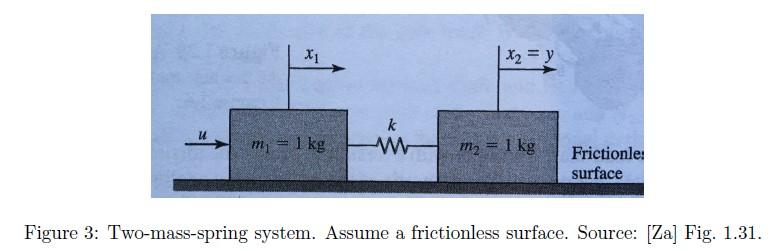

m1 = 1;
m2 = 1;
k = 1;

A = [0      0   1  0
        0      0   0  1
      -k/m1  k/m1  0  0
       k/m2 -k/m2  0  0];

B = [ 0
      0 
     1/m1
      0 ];

C = [ 0 1 0 0];

D = 0;

sys = ss(A,B,C,D);

eig(A)

ans =   -0.0000 + 1.4142i
  -0.0000 - 1.4142i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


Controllabilitry Gramians

% opt = gramOptions('TimeInterval', [0 10]);
% Wc = gram(sys,'c',opt);

cm = ctrb(A,B)

cm =      0     1     0    -1
     0     0     0     1
     1     0    -1     0
     0     0     1     0


rref(cm)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
